%Universidad del Cauca - 2021-1
%Teoria de las telecomunicaciones 1
%Trabajo 2 - Grupo 12 - Nicolas Chicaiza y Nicolas Zambrano

clear; %Limpio Espacio de trabajo
clc;

A=1; %Amplitud rampa (Multiplicacion por un escalar)
sh=1; %Desplazamiento en el tiempo (Normalizado solo para valores positivos)
T=4; %Periodo rampa (Igual al taller 1)
esc=1; %Cambio de Escala
shf=0; %Desplazamiento en frecuencia
np=0.001; %Espacio numerico definido en el periodo de la funcion (np=Numero de muestras en un periodo)
fs=1/(T*np); %Frecuencia de muestreo
t=-(T+sh):np*T:(T+sh); %Limites del espacio numerico (eje de abscisas ¨tiempo¨)


ramp=(A/T)*((t*esc)+sh); %Defino la pendiente de las rampas y creo el vector rampa con respecto al tiempo
ps=ramp.*rectpuls(((t*esc)+sh)-(T/2),(T)); %Acoto el vector rampa con un pulso rectangular de origen en 0 y ancho Tr
ps=ps.*exp(i*2*pi*shf*t);
%---------------------------CALCULO SIMBOLICO TRANSFORMADA--------------------------
%---------------------------Transformada pulso rampa--------------------------
syms x f;
dif=((A/T)*(((x*esc)+sh))*exp(i*2*pi*shf*x)*exp(-i*2*pi*f*x)) %Expresion dentro de la integral de la transformada de Fourier

$$dif = {\mathrm{e}}^{-2\,\pi \,f\,x\,\mathrm{i}}\,\left(\frac{x}{4}+\frac{1}{4}\right)$$

trfu=int(dif,[(0-sh)/esc (T-sh)/esc]) %Integral definida en el periodo de la rampa

$$trfu = \frac{{\mathrm{e}}^{-6\,\pi \,f\,\mathrm{i}}\,\left(1-{\mathrm{e}}^{8\,\pi \,f\,\mathrm{i}}+8\,\pi \,f\,\mathrm{i}\right)}{16\,f^{2}\,\pi^{2}}$$

trfua=simplify(abs(trfu))

$$trfua = \frac{{\mathrm{e}}^{6\,\pi \,\mathrm{imag}\left(f\right)}\,\left|1-{\mathrm{e}}^{8\,\pi \,f\,\mathrm{i}}+8\,\pi \,f\,\mathrm{i}\right|}{16\,\pi^{2}\,{\left|f\right|}^{2}}$$

double(limit(trfua))%evaluo el limite de la transformada simbolica en 0 para verificar amplitud del nivel DC

ans = 2

double(simplify(abs(limit(trfua,f,1))))%evaluo el limite de la transformada simbolica en 0 para verificar amplitud en f=1

ans = 0.1592

%-----------------------------------------------------------------------------

%---------------------------CALCULO SIMBOLICO TRANSFORMADA INVERSA--------------------------
%---------------------------TF Inversa para demostracion de dualidad--------------------------
%syms x f;
%difi=(trfu*exp(i*2*pi*f*(x))) %Expresion dentro de la integral de la transformada de Fourier
%trfi=int(difi,'f',[-inf inf]) %Integral definida en el periodo de la rampa
%trfi=simplify(abs(trfi))
%double(limit(trfi))%evaluo el limite de la transformada simbolica en 0 para verificar amplitud del nivel DC
%double(simplify(abs(subs(trfi,f,1))))%evaluo el limite de la transformada simbolica en 0 para verificar amplitud en f=1
%-----------------------------------------------------------------------------

%---------------------------TRANSFORMADA DESDE LA EXPRESION SIMBOLICA------------------------
%---------------------------TF Simbolica--------------------------
tic
Pts=983;%Numero de muestras a evaluar en la ecuacion simbolica
fsimb=linspace(-3,3,Pts);
Xfsimb=linspace(0,0,Pts);
for(n=1:length(fsimb))
    if(fsimb(n)==shf) %Condicional para evitar la indeterminacion de la expresion simbolica en f=shf
        Xfsimb(n)=limit(trfua,f,fsimb(n))
    else
        Xfsimb(n)=subs(trfua,f,fsimb(n));
    end
end

Xfsimb =     0.0531    0.0533    0.0535    0.0537    0.0539    0.0541    0.0543    0.0545    0.0546    0.0548    0.0549    0.0550    0.0551    0.0552    0.0552    0.0553    0.0553    0.0554    0.0554    0.0554    0.0554    0.0554    0.0554    0.0554    0.0554    0.0554    0.0554    0.0555    0.0555    0.0556    0.0557    0.0558    0.0560    0.0561    0.0563    0.0565    0.0567    0.0569    0.0571    0.0574    0.0576    0.0579    0.0582    0.0584    0.0587    0.0589    0.0591    0.0594    0.0596    0.0598


tiesimbolica=toc

tiesimbolica = 8.6968

%-----------------------------------------------------------------------------


%--------------------CALCULO FFT---------------------------
tic
Pt=10;%Coeficiente multiplicador de cantidad de puntos en la transformada rapida de Fourier
N=Pt*(2^(nextpow2(length(ps))));%Calculo de la potencia de 2 mas cercana a la longitud de la señal de entrada (Para eficiencia computacional)
Tf=fft(ps,N);
Xf=abs(fftshift(Tf))/fs; % Transformada FFT Normalizada
f=linspace(-fs/2,fs/2,length(Xf));
%f=f./T;%Normalizacion en frecuencia
tierapida=toc

tierapida = 0.0161

%-----------------------------------------------------------------------------

ratioabs=N/length(t); %razon entre el tamaño del vector tiempo y el tamaño del vector de la transformada de Fourier
ratiotf=tiesimbolica/tierapida;
%--------------------CALCULO FFT Inversa---------------------------
tic
Xt=abs(fftshift(fft(Tf))/N); % Transformada FFT Normalizada
ti=linspace(-ratioabs*(T+sh),ratioabs*(T+sh),length(Xt)); %Espacio vectorial del tiempo normalizado
ti=ti+(T+sh); %corrimiento del vector tiempo para ajuste de desfase
tieinversa=toc

tieinversa = 0.0093

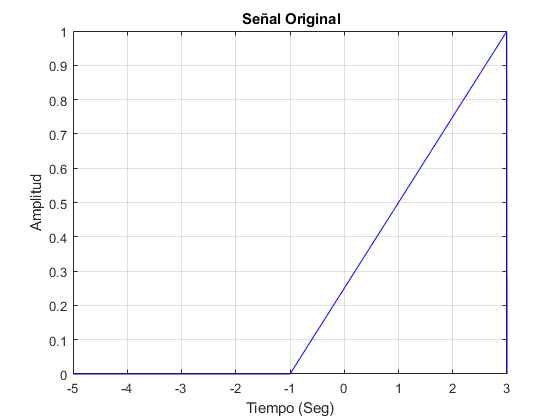

%-----------------------------------------------------------------------------

%--------------------Graficacion de Resultados---------------------------
plot(t,abs(ps),'b'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud;xlim([-T-sh T-sh]); %Graficacion de Resultados
title('\bf Señal Original');

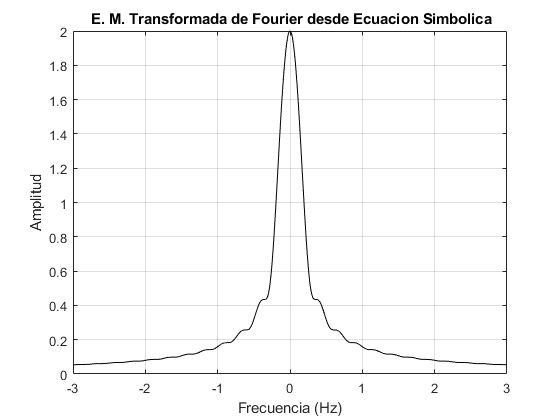

plot(fsimb,Xfsimb,'black'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-3 3]); %Graficacion de Resultados
title('\bf E. M. Transformada de Fourier desde Ecuacion Simbolica');

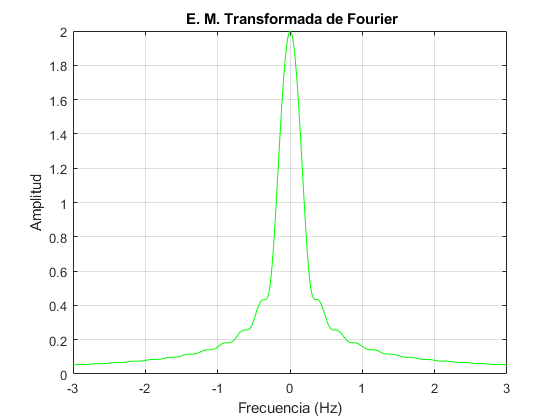

plot(f,Xf,'g'),grid on,xlabel 'Frecuencia (Hz)', ylabel Amplitud;xlim([-3 3]); %Graficacion de Resultados
title('\bf E. M. Transformada de Fourier');

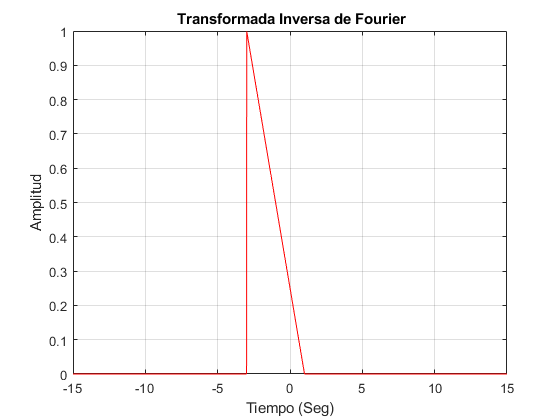

plot(ti,Xt,'r'),grid on,xlabel 'Tiempo (Seg)', ylabel Amplitud;xlim([-(T-sh)*5 (T-sh)*5]); %Graficacion de Resultados
title('\bf Transformada Inversa de Fourier');

%-----------------------------------------------------------------------------